**Resize and Place each picture in the appropriate square**

- **Each person's picture is 100x100 pixels**

- **Maggie goes into the red square **

- **Lisa goes into the green square **

- **Marge goes into the blue square **

- **Bart goes into the magenta square**

- **Homer goes into the cyan square **

- **The family photo goes into the yellow square **

- **All colors are "pure"**

Import images

frame = imread('simpsonsFrame.png');
bart = imread('bart.jpg');
lisa = imread('lisa.jpg');
homer = imread('homer.jpg');
marge = imread('marge.jpg');
maggie = imread('maggie.jpg');
family = imread('family.jpg');


Show frame

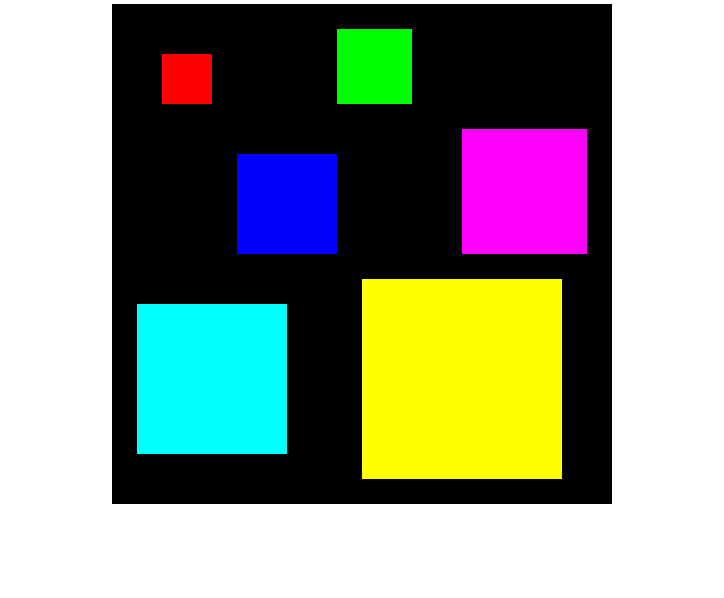


imshow(frame);

frame

frame = 500×500×3 uint8 array
frame(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

Show pics

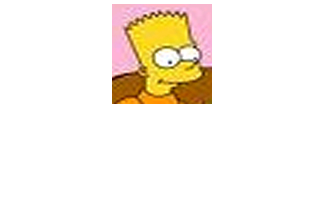

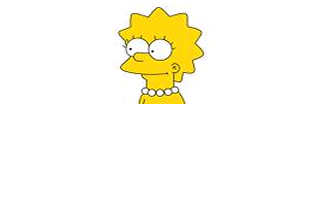

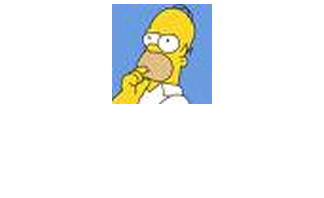

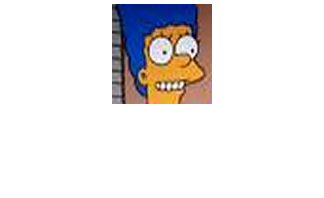

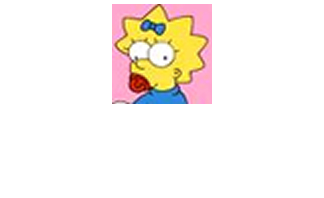

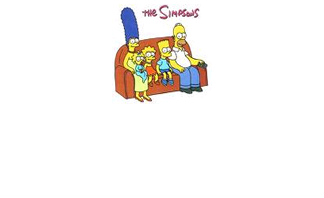

pics = {bart, lisa, homer, marge, maggie, family};
for index = 1:length(pics)
    figure
    imshow(pics{index});
end

Create Mask and Place pics in appropriate frames

Maggie

%Create color mask to find the square
mask2d = frame(:,:,1)==255 & frame(:,:,2)==0 & frame(:,:,3)==0; 
%Calculate height and width of square
[rows, cols] = find(mask2d);
height = max(rows)-min(rows)+1;
width = max(cols)-min(cols)+1;

%Make a 3d mask to mask the frame image
mask3d = cat(3, mask2d, mask2d, mask2d); 
%Resize image and mask into frame
frame(mask3d) = imresize(maggie,[height, width]);

Lisa

%Create color mask to find the square
mask2d = frame(:,:,1)==0 & frame(:,:,2)==255 & frame(:,:,3)==0; 
%Calculate height and width of square
[rows, cols] = find(mask2d);
height = max(rows)-min(rows)+1;
width = max(cols)-min(cols)+1;

%Make a 3d mask to mask the frame image
mask3d = cat(3, mask2d, mask2d, mask2d); 
%Resize image and mask into frame
frame(mask3d) = imresize(lisa,[height, width]);


Marge

%Create color mask to find the square
mask2d = frame(:,:,1)==0 & frame(:,:,2)==0 & frame(:,:,3)==255; 
%Calculate height and width of square
[rows, cols] = find(mask2d);
height = max(rows)-min(rows)+1;
width = max(cols)-min(cols)+1;

%Make a 3d mask to mask the frame image
mask3d = cat(3, mask2d, mask2d, mask2d); 
%Resize image and mask into frame
frame(mask3d) = imresize(marge,[height, width]);


Bart

%Create color mask to find the square
mask2d = frame(:,:,1)==255 & frame(:,:,2)==0 & frame(:,:,3)==255; 
%Calculate height and width of square
[rows, cols] = find(mask2d);
height = max(rows)-min(rows)+1;
width = max(cols)-min(cols)+1;

%Make a 3d mask to mask the frame image
mask3d = cat(3, mask2d, mask2d, mask2d); 
%Resize image and mask into frame
frame(mask3d) = imresize(bart,[height, width]);

Marge

%Create color mask to find the square
mask2d = frame(:,:,1)==0 & frame(:,:,2)==255 & frame(:,:,3)==255; 
%Calculate height and width of square
[rows, cols] = find(mask2d);
height = max(rows)-min(rows)+1;
width = max(cols)-min(cols)+1;

%Make a 3d mask to mask the frame image
mask3d = cat(3, mask2d, mask2d, mask2d); 
%Resize image and mask into frame
frame(mask3d) = imresize(homer,[height, width]);

Family

%Create color mask to find the square
mask2d = frame(:,:,1)==255 & frame(:,:,2)==255 & frame(:,:,3)==0; 
%Calculate height and width of square
[rows, cols] = find(mask2d);
height = max(rows)-min(rows)+1;
width = max(cols)-min(cols)+1;

%Make a 3d mask to mask the frame image
mask3d = cat(3, mask2d, mask2d, mask2d); 
%Resize image and mask into frame
frame(mask3d) = imresize(family,[height, width]);


Show final frame

frame = rgb2gray(frame)

frame = 500×500 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

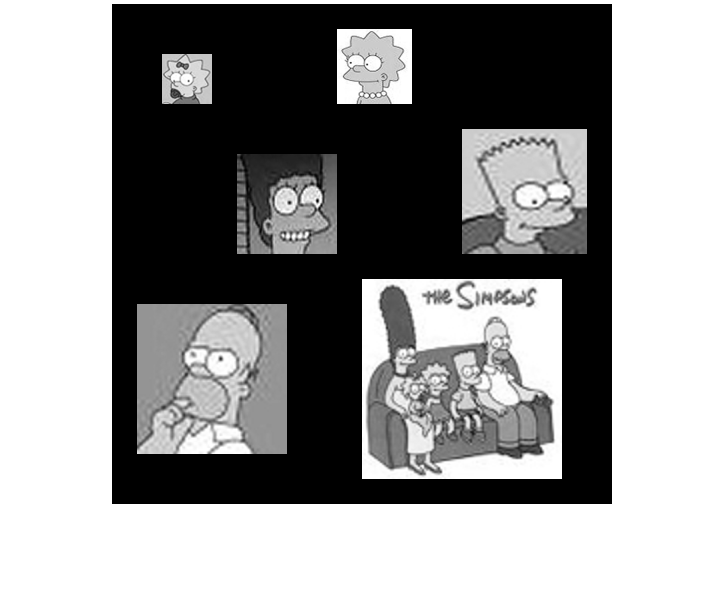

imshow(frame);

imwrite(frame,'finshedSimpsonsPhotoFrame.png');